Let's approximate $e^x$ over the interval $[-1,1]$. We can sample it at, say, 40 points, and find the best-fitting straight line to that data. 

t = linspace(-1,1,40)';
y = exp(t);
plot(t,y,'.')
V = [t.^0 t];
c = V\y

c =    1.184649280033524
   1.109055176467003


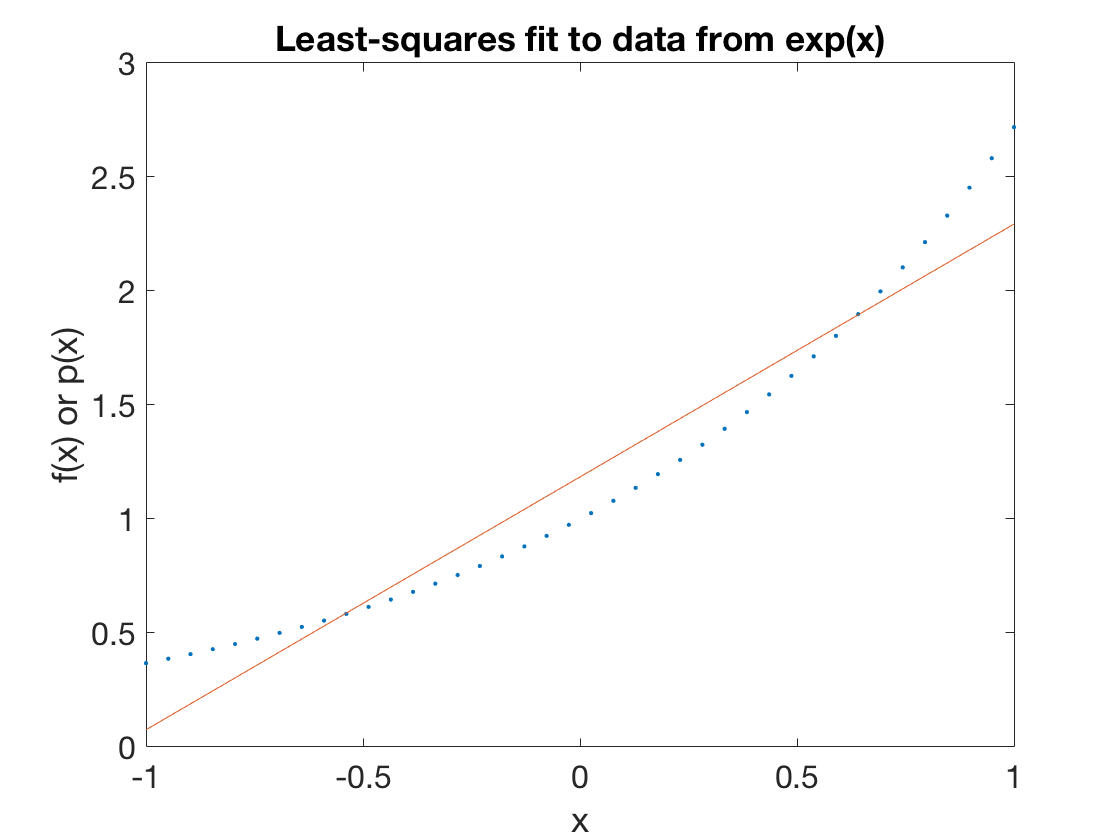

p = @(t) c(1) + c(2)*t;
hold on, fplot(p,[-1 1])
title('Least-squares fit to data from exp(x)')    % ignore this line
xlabel('x'), ylabel('f(x) or p(x)')    % ignore this line

There's nothing special about 40 points. By choosing more we get closer to the ``true'' $e^x$.

t = linspace(-1,1,200)';
y = exp(t);
V = [t.^0 t];
c = V\y

c =    1.177050433389150
   1.104713796900292


t = linspace(-1,1,1000)';
y = exp(t);
V = [t.^0 t];
c = V\y

c =    1.175569465210804
   1.103853093670791


It's quite plausible that the coefficients of the best-fit line are approaching a limit as the number of nodes goes to infinity. 